# Comparison of dopaminergic neuronal metabolism predictions using iDopaNeuroC and iDopaNeuroCT

Load the models

[~, ~] = changeCobraSolver('mosek', 'all', 0);
tcbmParam.solver = 'mosek';

% specificData folder
if contains(char(java.lang.System.getProperty('user.name')),'aga')
    dataFolder = ['~' filesep 'work' filesep 'sbgCloud' filesep 'exoMetDN' ...
        filesep 'data' filesep 'xomics'];
    modelsDir = ['~' filesep 'work' filesep 'sbgCloud' filesep 'exoMetDN' ...
        filesep 'results' filesep 'codeResults' filesep 'iDN1'];
    resultsDir=['~' filesep 'work' filesep 'sbgCloud' filesep 'exoMetDN' ...
        filesep 'results' filesep 'codeResults' filesep 'iDN1' filesep 'iDopaNeuroCvsCT'];
else
    dataFolder = ['~' filesep 'work' filesep 'sbgCloud' filesep ...
        'programReconstruction' filesep 'projects' filesep 'exoMetDN' ...
        filesep 'data' filesep 'xomics'];
    modelsDir = ['~' filesep 'work' filesep 'sbgCloud' filesep ...
        'programReconstruction' filesep 'projects' filesep 'exoMetDN' ...
        filesep 'results' filesep 'codeResults' filesep 'iDN1'];
    resultsDir=['~' filesep 'work' filesep 'sbgCloud' filesep ...
        'programReconstruction' filesep 'projects' filesep 'exoMetDN' ...
        filesep 'results' filesep 'codeResults' filesep 'iDN1' filesep 'iDopaNeuroCvsCT'];
end

%filenames
bibliomicData = 'bibliomicData.xlsx';
exometabolomicData = 'exometabolomicData.txt';
transcriptomicData = 'transcriptomicData.txt';

%load both iDopaNeuroCs
load([modelsDir filesep 'iDopaNeuroC' filesep 'iDopaNeuroC.mat']);
load([modelsDir filesep 'iDopaNeuroCT' filesep 'iDopaNeuroCT.mat']);

resultsDir='~/work/sbgCloud/programReconstruction/projects/exoMetDN/results/codeResults/iDN1/iDopaNeuroCvsCT';
if ~exist(resultsDir,'dir')
    mkdir(resultsDir)
end

%some minor adjustments to the models
if isfield(iDopaNeuroC, 'g0')
    iDopaNeuroC = rmfield(iDopaNeuroC, 'g0');
end
if isfield(iDopaNeuroC, 'g1')
    iDopaNeuroC = rmfield(iDopaNeuroC, 'g1');
end
if isfield(iDopaNeuroCT, 'g0')
    iDopaNeuroCT = rmfield(iDopaNeuroCT, 'g0');
end
if isfield(iDopaNeuroCT, 'g1')
    iDopaNeuroCT = rmfield(iDopaNeuroCT, 'g1');
end

Save the vanilla iDopaNeuroC and iDopaNeuroCT models prior to any adjustments

iDopaNeuroC = changeRxnBounds(iDopaNeuroC, 'EX_gal[e]', 0, 'b'); %galactose not present in the medium
iDopaNeuroCOrg = iDopaNeuroC;
iDopaNeuroCT = changeRxnBounds(iDopaNeuroCT, 'EX_gal[e]', 0, 'b'); %galactose not present in the medium
iDopaNeuroCTOrg = iDopaNeuroCT;

Manual correction of some exchange reactions lower boundaries

rxnsList = {'EX_atp[e]', 'EX_dopa[e]', 'EX_dopasf[e]', 'EX_h2o2[e]', 'EX_dopa4sf[e]', ...
    'EX_dopa4glcur[e]', 'EX_dopa3glcur[e]', 'EX_4glu56dihdind[e]', 'EX_5cysdopa[e]', 'EX_CE5025[e]'};
iDopaNeuroC = changeRxnBounds(iDopaNeuroC, rxnsList, 0, 'l');
iDopaNeuroCOrig = iDopaNeuroC;
iDopaNeuroCT = changeRxnBounds(iDopaNeuroCT, rxnsList, 0, 'l');
iDopaNeuroCTOrig = iDopaNeuroCT;

## Core reactions venn diagram

% Read activeReactions
specificData = preprocessingOmicsModel([dataFolder filesep bibliomicData], 1, 1);

Reading inputData from : ~/work/sbgCloud/programReconstruction/projects/exoMetDN/data/xomics/bibliomicData.xlsx
Reading sheet: activeGenes
Reading sheet: activeReactions
Reading sheet: cellCultureData
Reading sheet: coupledRxns
Reading sheet: essentialAA
Reading sheet: inactiveGenes
Reading sheet: mediaData
Reading sheet: presentMetabolites
Reading sheet: rxns2add
Reading sheet: rxns2constrain
Reading sheet: rxnsHypothesis
Reading sheet: rxns2remove
Reading sheet: sinkDemand


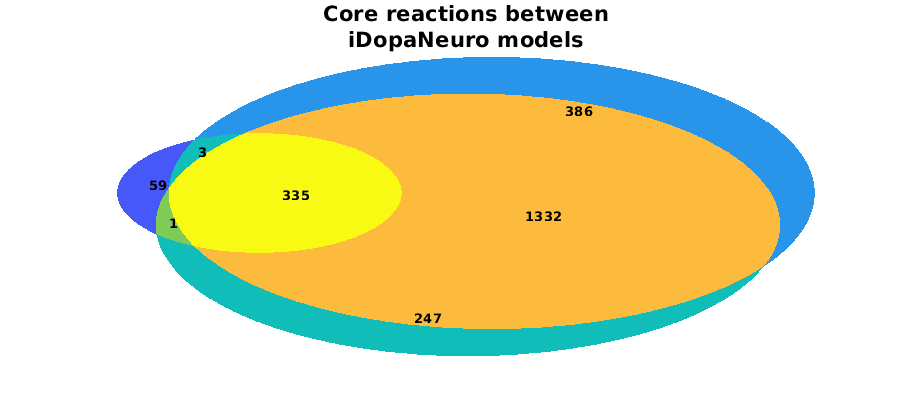

% coreRxnAbbr
coreRxnAbbr = {};
coreRxnAbbr = [coreRxnAbbr; specificData.activeReactions];
coreRxnAbbr = [coreRxnAbbr; specificData.rxns2constrain.rxns];
for i = 1:length(specificData.coupledRxns.coupledRxnsList)
    coreRxnAbbr = [coreRxnAbbr; split(specificData.coupledRxns.coupledRxnsList{i}, ', ')];
end
coreRxnAbbr = [coreRxnAbbr; specificData.mediaData.rxns];
coreRxnAbbr = unique(coreRxnAbbr);

%% Generate diagram
set7 = numel(intersect(iDopaNeuroC.rxns, intersect(iDopaNeuroCT.rxns, coreRxnAbbr)));
vennX([numel(setdiff(coreRxnAbbr, [iDopaNeuroCT.rxns; iDopaNeuroC.rxns])) ...
    numel(intersect(coreRxnAbbr, iDopaNeuroCT.rxns))  - set7 ...
    numel(setdiff(iDopaNeuroCT.rxns, [coreRxnAbbr; iDopaNeuroC.rxns]))  ...
    numel(intersect(iDopaNeuroC.rxns, iDopaNeuroCT.rxns))  - set7 ...
    numel(setdiff(iDopaNeuroC.rxns, [iDopaNeuroCT.rxns; coreRxnAbbr]))  ...
    numel(intersect(coreRxnAbbr, iDopaNeuroC.rxns))  - set7 ...
    set7], .01);
title({'Core reactions between', 'iDopaNeuro models'}, 'FontSize', 16)
savefig([resultsDir filesep 'coreRxnsComparisonVenn'])
saveas(gcf,[resultsDir filesep 'coreRxnsComparisonVenn'],'png')

## Read in metabolomic data

exoMet = readtable([dataFolder filesep 'exometabolomicData.txt']);
if isvar(exoMet,'rxnID')
    exoMet.Properties.VariableNames{'rxnID'} = 'rxns';
end
if isvar(exoMet,'metID')
    exoMet.Properties.VariableNames{'metID'} = 'mets';
end
if isvar(exoMet,'metName')
    exoMet.Properties.VariableNames{'metName'} = 'metNames';
end

Hack to replace 0 0 with NaN

[mlt,nlt]=size(exoMet);
for i=1:mlt
    for j = 7:2:nlt
        if exoMet{i,j}==0 && exoMet{i,j+1}==0
            exoMet{i,j}=NaN;
            exoMet{i,j+1}=NaN;
        end
    end
end

## Map the exometabolomic data onto the iDopaNeuroC

[exoMet,LIBkey,LOCAkey] = mapAontoB(exoMet.rxns,iDopaNeuroC.rxns,exoMet);
exoMet = exoMet(LIBkey,:);

## Extract the exometabolomic data

Control exometabolomic data with glucose uptake

glcValidationData = exoMet(:, 1:4);
glcValidationData(:, end+1) = table(exoMet.mean);
glcValidationData(:, end+1) = table(exoMet.SD);
glcValidationData.Properties.VariableNames{'Var5'} = 'mean';
glcValidationData.Properties.VariableNames{'Var6'} = 'SD';
glcValidationData.Properties.Description='Exometabolomic Glucose medium';
glcValidationData = glcValidationData(~isnan(glcValidationData.mean),:);
glcValidationData = sortrows(glcValidationData, 'rxns');

## Table with comparisons

Objectives to be used:
  1×1 cell array

    {'unWeightedTCBMflux'}

Using existing internal net flux bounds without modification.



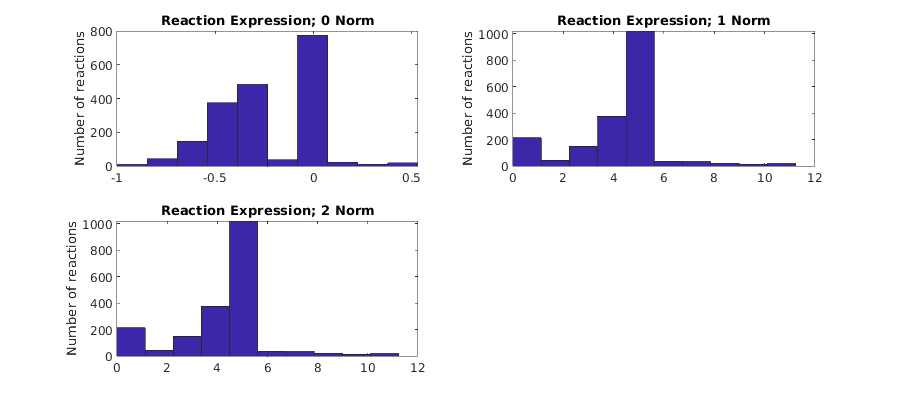

MOSEK Version 9.2.37 (Build date: 2021-2-8 10:03:08)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 13225           
  Cones                  : 3420            
  Scalar variables       : 17306           
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.01            
Lin. dep.  - number                 : 25              
Presolve terminated. Time: 0.05    
Problem
  Name     

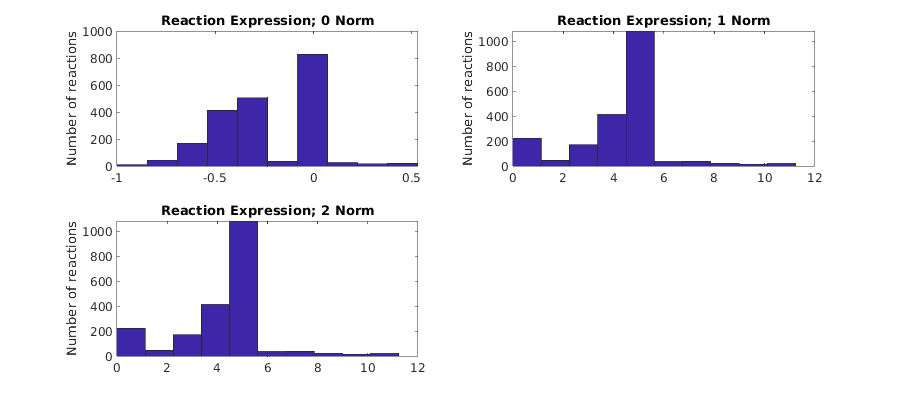

MOSEK Version 9.2.37 (Build date: 2021-2-8 10:03:08)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 14217           
  Cones                  : 3684            
  Scalar variables       : 18635           
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.01            
Lin. dep.  - number                 : 28              
Presolve terminated. Time: 0.03    
Problem
  Name     

MOSEK Version 9.2.37 (Build date: 2021-2-8 10:03:08)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 13225           
  Cones                  : 3420            
  Scalar variables       : 17306           
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 25              
Presolve terminated. Time: 0.03    
Problem
  Name     

  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer  - threads                : 4               
Optimizer  - solved problem         : the primal      
Optimizer  - Constraints            : 2933
Optimizer  - Cones                  : 3684
Optimizer  - Scalar variables       : 12979             conic                  : 11052           
Optimizer  - Semi-definite variables: 0                 scalarized             : 0               
Factor     - setup time             : 0.01              dense det. time        : 0.00            
Factor     - ML order time          : 0.00              GP order time          : 0.00            
Factor     - nonzeros before factor : 1.63e+04          after factor           : 2.65e+04        
Factor     - dense dim.             : 0                 flops                  : 9.84e+05        
ITE PFEAS    DFEAS    GFEAS    PRSTATUS   POBJ              DOBJ              MU       TIME  
0   1.0e+04  1.2e+00  1.1e+04  0.

comparisonTable = 25×2 table
                                              iDopaNeuroC    iDopaNeuroCT
                                              ___________    ____________

    Metabolites                                {[1244]}        {[1312]}  
    Unique metabolites                         {[ 664]}        {[ 685]}  
    Reactions                                  {[1915]}        {[2056]}  
    rank(S)                                    {[1161]}        {[1218]}  
    Genes                                      {[1212]}        {[1229]}  
    Subsystems                                 {[  78]}        {[  77]}  
    Metabolites in cytosol                     {[ 586]}        {[ 598]}  
    Metabolites in extracellular               {[ 234]}        {[ 248]}  
    Metabolites in

models.iDopaNeuroC = iDopaNeuroC;
models.iDopaNeuroCT = iDopaNeuroCT;
param.objectives = {'unWeightedTCBMflux'};
param.trainingSet = glcValidationData;
param.tests = {'flux'};
[comparisonResults, comparisonTable] = compareModelsFeatures(models, param);

display(comparisonTable)

comparisonTable = 25×2 table
                                              iDopaNeuroC    iDopaNeuroCT
                                              ___________    ____________

    Metabolites                                {[1244]}        {[1312]}  
    Unique metabolites                         {[ 664]}        {[ 685]}  
    Reactions                                  {[1915]}        {[2056]}  
    rank(S)                                    {[1161]}        {[1218]}  
    Genes                                      {[1212]}        {[1229]}  
    Subsystems                                 {[  78]}        {[  77]}  
    Metabolites in cytosol                     {[ 586]}        {[ 598]}  
    Metabolites in extracellular               {[ 234]}        {[ 248]}  
    Metabolites in

## Control predictions

Predict fluxes with EFBA

tcbmParam.method = 'fluxes';
tcbmParam.printLevel = 0;
iDopaNeuroC.osenseStr = 'min';
iDopaNeuroC.cf = 0;
iDopaNeuroC.cr = 0;
iDopaNeuroC.g = 2;
iDopaNeuroC.u0 = 0;
iDopaNeuroC.f = 1;
       
% control flux
[sol, ~] = entropicFluxBalanceAnalysis(iDopaNeuroC, tcbmParam);
iDopaNeuroC_EFBA = table(iDopaNeuroC.rxns, iDopaNeuroC.rxnFormulas, iDopaNeuroC.lb, iDopaNeuroC.ub);
iDopaNeuroC_EFBA.Properties.VariableNames = {'rxns', 'rxnFormulas', 'lb', 'ub'};
iDopaNeuroC_EFBA.v = sol.v;
iDopaNeuroC_EFBA.Properties.Description='iDopaNeuroC, EFBA Prediction, Glucose medium';

[sol, ~] = entropicFluxBalanceAnalysis(iDopaNeuroCT, tcbmParam);
iDopaNeuroCT_EFBA = table(iDopaNeuroCT.rxns, iDopaNeuroCT.rxnFormulas, iDopaNeuroCT.lb, iDopaNeuroCT.ub);
iDopaNeuroCT_EFBA.Properties.VariableNames = {'rxns', 'rxnFormulas', 'lb', 'ub'};
iDopaNeuroCT_EFBA.v = sol.v;
iDopaNeuroCT_EFBA.Properties.Description='iDopaNeuroCT, EFBA Prediction, Glucose medium';

Plot predictions with corresponding experimental data

param.expOrder = 1;
param.predictedBounds = 1;
param.otherBounds = 1;
plotExperimentalvsPredictedExchange(glcValidationData, iDopaNeuroC_EFBA, iDopaNeuroCT_EFBA, [], param)

16 of 47 abs(mean) < SD in experimental data
iDopaNeuroC, EFBA Prediction, Glucose medium,            Spearman correlation = 0.996774, pval = 0, qualAccuracy = 1, N = 31
iDopaNeuroC, EFBA Prediction, Glucose medium,    Finite, Spearman correlation = 0.738899, pval = 2.57547e-08, qualAccuracy = 0.744681, N = 47
iDopaNeuroC, EFBA Prediction, Glucose medium, Upt & Sec, Spearman correlation = 0.996774, pval = 0, qualAccuracy = 1, N = 31
iDopaNeuroC, EFBA Prediction, Glucose medium,  Upt only, Spearman correlation = 0.987879, pval = 0, qualAccuracy = 1, N = 10
iDopaNeuroC, EFBA Prediction, Glucose medium,  Sec only, Spearman correlation = 0.990909, pval = 4.30607e-06, qualAccuracy = 1, N = 21
16 of 47 abs(mean) < SD in experimental data
iDopaNeuroCT, EFBA Prediction, Glucose medium,            Spearman correlation = 0.997581, pval = 0, qualAccuracy = 1, N = 31
iDopaNeuroCT, EFBA Prediction, Glucose medium,    Finite, Spearman correlation = 0.741674, pval = 2.14856e-08, qualAccuracy = 0.7446

Predictions without corresponding experimental data

tol=0.5;
param.rxns =intersect(iDopaNeuroC.rxns(~ismember(iDopaNeuroC.rxns,glcValidationData.rxns) & ~iDopaNeuroC.SConsistentRxnBool & abs(iDopaNeuroC_EFBA.v)>tol),...
    iDopaNeuroCT.rxns(~ismember(iDopaNeuroCT.rxns,glcValidationData.rxns) & ~iDopaNeuroCT.SConsistentRxnBool & abs(iDopaNeuroCT_EFBA.v)>tol));
param.predictedBounds = 0;
param.otherBounds = 0;
iDopaNeuroC_EFBA.labels = iDopaNeuroC.rxnNames;
rxnsOut = plotPredictedExchange(iDopaNeuroC_EFBA, iDopaNeuroCT_EFBA, [], param);
disp(rxnsOut(1:10))

    {'EX_o2[e]'    }
    {'EX_h2o[e]'   }
    {'EX_CE1554[e]'}
    {'EX_CE5629[e]'}
    {'DM_ps_hs[c]' }
    {'EX_glu_L[e]' }
    {'EX_inost[e]' }
    {'EX_asp_L[e]' }
    {'EX_CE1261[e]'}
    {'EX_urcan[e]' }



## Plot comparison of prediction with experimental data

param.expOrder = 1; %1  = order reactions by value of experimental flux
param.predictedBounds=1;
plotExperimentalvsPredictedExchange(glcValidationData, iDopaNeuroC_EFBA, iDopaNeuroCT_EFBA, [], param)

16 of 47 abs(mean) < SD in experimental data
iDopaNeuroC, EFBA Prediction, Glucose medium,            Spearman correlation = 0.996774, pval = 0, qualAccuracy = 1, N = 31
iDopaNeuroC, EFBA Prediction, Glucose medium,    Finite, Spearman correlation = 0.738899, pval = 2.57547e-08, qualAccuracy = 0.744681, N = 47
iDopaNeuroC, EFBA Prediction, Glucose medium, Upt & Sec, Spearman correlation = 0.996774, pval = 0, qualAccuracy = 1, N = 31
iDopaNeuroC, EFBA Prediction, Glucose medium,  Upt only, Spearman correlation = 0.987879, pval = 0, qualAccuracy = 1, N = 10
iDopaNeuroC, EFBA Prediction, Glucose medium,  Sec only, Spearman correlation = 0.990909, pval = 4.30607e-06, qualAccuracy = 1, N = 21
16 of 47 abs(mean) < SD in experimental data
iDopaNeuroCT, EFBA Prediction, Glucose medium,            Spearman correlation = 0.997581, pval = 0, qualAccuracy = 1, N = 31
iDopaNeuroCT, EFBA Prediction, Glucose medium,    Finite, Spearman correlation = 0.741674, pval = 2.14856e-08, qualAccuracy = 0.7446

## Fit the models exchanges to the exometabolomic constraints from the glucose medium condition

Fit a control models to experimentally measured fluxes while maximising flux entropy and maximising a linear objective on reaction flux. Add the additional quadratic terms to the iDopaNeuroC to be solved with EFBA and relax the bounds on the reactions with exometabolomic constraints from the control condition

param.alpha=1e5;
param.printLevel=1;
param.relaxBounds=1;
iDopaNeuroC = addExoMetToEFBA(iDopaNeuroCOrig,glcValidationData,param);
iDopaNeuroCT = addExoMetToEFBA(iDopaNeuroCTOrig,glcValidationData,param);

[sol, ~] = entropicFluxBalanceAnalysis(iDopaNeuroC, tcbmParam);
iDopaNeuroC_QEFBA = iDopaNeuroC_EFBA;
iDopaNeuroC_QEFBA.v = sol.v;
iDopaNeuroC_QEFBA.Properties.Description='iDopaNeuroC, QEFBA Prediction, Glucose medium';
disp(sol)

            time: 0.6316
            stat: 1
        origStat: 'OPTIMAL'
        dualNorm: [0×1 double]
             obj: 3.6827e+05
       objLinear: 0
      objEntropy: -5.1721e+03
    objQuadratic: 3.6309e+05
        lagRcost: 0.3824
          solver: 'mosek'
               v: [1915×1 double]
              vf: [1710×1 double]
              vr: [1710×1 double]
              vt: 3.8887e+03
             y_N: [1244×1 double]
             y_v: [1915×1 double]
            z_dx: 0
            z_vf: [1710×1 double]
            z_vr: [1710×1 double]
            z_vi: [1710×1 double]
             z_v: [1915×1 double]
          osense: -1
             y_C: [11×1 double]
        messages: []



[sol, ~] = entropicFluxBalanceAnalysis(iDopaNeuroCT, tcbmParam);
iDopaNeuroCT_QEFBA = iDopaNeuroCT_EFBA;
iDopaNeuroCT_QEFBA.v = sol.v;
iDopaNeuroCT_QEFBA.Properties.Description='iDopaNeuroCT, QEFBA Prediction, Glucose medium';
disp(sol)

            time: 0.5961
            stat: 1
        origStat: 'OPTIMAL'
        dualNorm: [0×1 double]
             obj: 3.3638e+05
       objLinear: 0
      objEntropy: -4.8083e+03
    objQuadratic: 3.3157e+05
        lagRcost: -0.1202
          solver: 'mosek'
               v: [2056×1 double]
              vf: [1842×1 double]
              vr: [1842×1 double]
              vt: 4.0720e+03
             y_N: [1312×1 double]
             y_v: [2056×1 double]
            z_dx: 0
            z_vf: [1842×1 double]
            z_vr: [1842×1 double]
            z_vi: [1842×1 double]
             z_v: [2056×1 double]
          osense: -1
             y_C: [11×1 double]
        messages: []



## Fitting of measured exchanges

param.saveFigures=0;
param.expOrder = 1; %1  = order reactions by value of experimental flux
param.predictedBounds=1;
param.otherBounds=0;
param.extraBounds=0;
plotExperimentalvsPredictedExchange(glcValidationData, iDopaNeuroC_EFBA, iDopaNeuroC_QEFBA, iDopaNeuroCT_QEFBA, param)

16 of 47 abs(mean) < SD in experimental data
iDopaNeuroC, EFBA Prediction, Glucose medium,            Spearman correlation = 0.996774, pval = 0, qualAccuracy = 1, N = 31
iDopaNeuroC, EFBA Prediction, Glucose medium,    Finite, Spearman correlation = 0.738899, pval = 2.57547e-08, qualAccuracy = 0.744681, N = 47
iDopaNeuroC, EFBA Prediction, Glucose medium, Upt & Sec, Spearman correlation = 0.996774, pval = 0, qualAccuracy = 1, N = 31
iDopaNeuroC, EFBA Prediction, Glucose medium,  Upt only, Spearman correlation = 0.987879, pval = 0, qualAccuracy = 1, N = 10
iDopaNeuroC, EFBA Prediction, Glucose medium,  Sec only, Spearman correlation = 0.990909, pval = 4.30607e-06, qualAccuracy = 1, N = 21
16 of 47 abs(mean) < SD in experimental data
iDopaNeuroC, QEFBA Prediction, Glucose medium,            Spearman correlation = 0.991129, pval = 0, qualAccuracy = 1, N = 31
iDopaNeuroC, QEFBA Prediction, Glucose medium,    Finite, Spearman correlation = 0.824006, pval = 0, qualAccuracy = 0.893617, N = 47

## Prediction of unmeasured exchanges

Plot the predicted exchanges with quadratic fitting of experimentally measured exchanges and entropic flux balance analysis

tol=0.5;
param.rxns =intersect(iDopaNeuroC.rxns(~ismember(iDopaNeuroC.rxns,glcValidationData.rxns) & ~iDopaNeuroC.SConsistentRxnBool & abs(iDopaNeuroC_EFBA.v)>tol),...
    iDopaNeuroCT.rxns(~ismember(iDopaNeuroCT.rxns,glcValidationData.rxns) & ~iDopaNeuroCT.SConsistentRxnBool & abs(iDopaNeuroCT_EFBA.v)>tol));
param.predictedBounds = 1;
param.otherBounds = 0;
param.exchangesOnly = 1;
iDopaNeuroC_QEFBA.labels = iDopaNeuroC.rxnNames;
plotPredictedExchange(iDopaNeuroC_QEFBA, iDopaNeuroCT_QEFBA, [], param)

## Perform Robustness Analysis

% Define parameters
tcbmParam.method = 'fluxes';
tcbmParam.printLevel = 0;

rxn2vary = 'ATPM';
fixedRxns = {'PGK'; 'PYK'; 'ATPtm'; 'EX_dopa[e]'};
range = (186/10):(186*10);
npoints = 100;
bound = 'b';

% find fixedRxns idx
iDNc_rxn2Idxs = findRxnIDs(iDopaNeuroC, fixedRxns);
iDNct_rxn2Idxs = findRxnIDs(iDopaNeuroCT, fixedRxns);

% Compute fluxes
[rx1, rx2] = deal(zeros(npoints, 1));
bounds = min(range):(max(range) - min(range)) / npoints:max(range);
for i = 1:length(fixedRxns)
    
    for j = 1:length(bounds)
        
        % iDopaNeuroC
        iDNc = iDopaNeuroC;
        iDNc = changeRxnBounds(iDNc, rxn2vary, bounds(j), bound);
        [sol, ~] = entropicFluxBalanceAnalysis(iDNc, tcbmParam);
        iDNc_rx1(i,j) = bounds(j);
        iDNc_rx2(i,j) = sol.v(iDNc_rxn2Idxs(i));
        
        % iDopaNeuroCT
        iDNct = iDopaNeuroCT;
        iDNct = changeRxnBounds(iDNct, rxn2vary, bounds(j), bound);
        [sol,~] = entropicFluxBalanceAnalysis(iDNct, tcbmParam);
        iDNct_rx1(i,j) = bounds(j);
        iDNct_rx2(i,j) = sol.v(iDNct_rxn2Idxs(i));
        
    end
end

for i = 1:length(fixedRxns)
    sgtitle({'Phenotype of essential reactions when varying ATP demand'}, 'FontSize', 16)
    subplot(2, 2, i)
    plot(iDNc_rx1(i,:), iDNc_rx2(i,:), 'LineWidth', 2)
    hold on 
    plot(iDNct_rx1(i,:), iDNct_rx2(i,:), 'LineWidth', 2, 'Color', [0.9294 0.6941 0.1255])
    axis([min(range) max(range) min([iDNc_rx2(i,:) iDNct_rx2(i,:)]) max([iDNc_rx2(i,:) iDNct_rx2(i,:)])])
    xlabel([rxn2vary ' umol/gDW/hr'], 'FontSize', 12)
    ylabel([fixedRxns{i} ' umol/gDW/hr'], 'FontSize', 12,'Interpreter', 'none')
    title(iDopaNeuroCT.rxnNames{iDNct_rxn2Idxs(i)}, 'FontSize', 14)
    if i == 1
        legend({'iDopaNeuroC'; 'iDopaNeuroCT'}, 'Location', 'best', 'FontSize', 12)
    end
end

savefig([resultsDir filesep 'robustnessAnalysis'])

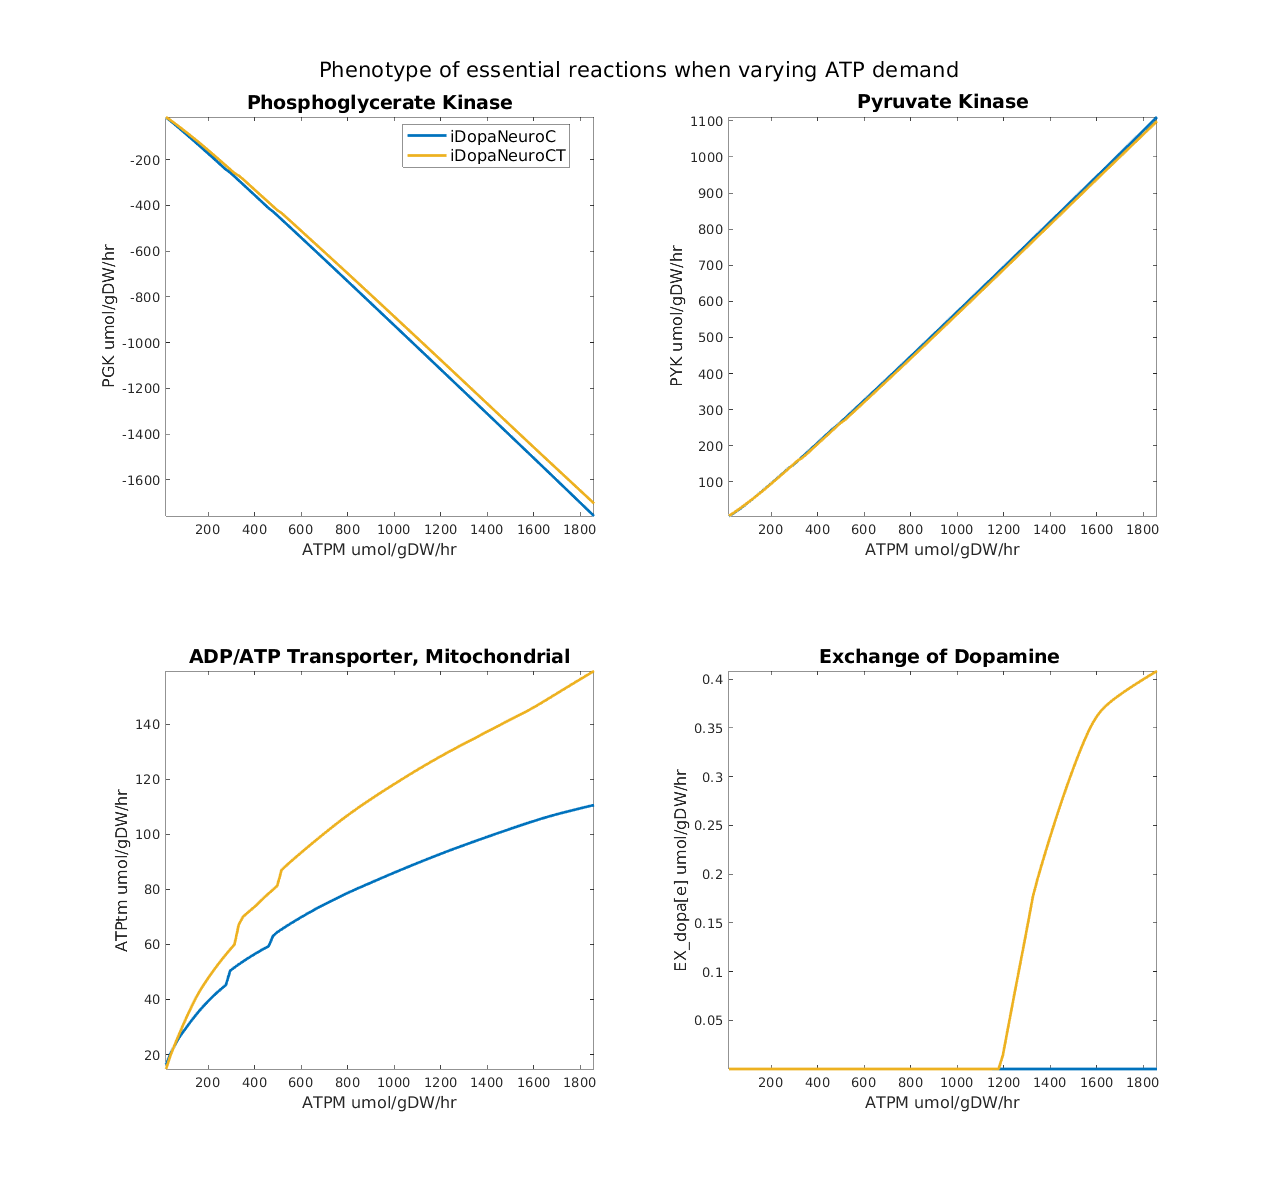

saveas(gcf,[resultsDir filesep 'robustnessAnalysis'],'png')

%saveas(gcf,[pathSave filesep 'rba'],'eps')

Leave one out cross validation on control glucose uptake models

LOOCVparam.alpha=1e5;
LOOCVparam.printLevel=1;
LOOCVparam.relaxBounds=1;

iDopaNeuroC = changeRxnBounds(iDopaNeuroCOrig, 'EX_gal[e]', 0, 'b'); %galactose not present in the medium
[iDopaNeuroC_LOOCV,LIBkey] = exoMetLOOCV(iDopaNeuroC,glcValidationData,LOOCVparam);
iDopaNeuroC_LOOCVPrediction = iDopaNeuroC_EFBA;
iDopaNeuroC_LOOCVPrediction.v = iDopaNeuroC_LOOCV.LOOCV;
iDopaNeuroC_LOOCVPrediction.Properties.Description='iDopaNeuroC LOOCV, QEFBA Prediction, Glucose medium';

iDopaNeuroCT = changeRxnBounds(iDopaNeuroCTOrig, 'EX_gal[e]', 0, 'b'); %galactose not present in the medium
[iDopaNeuroCT_LOOCV,LIBkey] = exoMetLOOCV(iDopaNeuroCT,glcValidationData,LOOCVparam);
iDopaNeuroC_LOOCVPrediction = iDopaNeuroC_EFBA;
iDopaNeuroC_LOOCVPrediction.v = iDopaNeuroC_LOOCV.LOOCV;
iDopaNeuroC_LOOCVPrediction.Properties.Description='iDopaNeuroC LOOCV, QEFBA Prediction, Glucose medium';
iDopaNeuroCT_LOOCVPrediction = iDopaNeuroC_EFBA;
iDopaNeuroCT_LOOCVPrediction.Properties.Description='iDopaNeuroCT LOOCV, QEFBA Prediction, Glucose medium';

16 of 47 abs(mean) < SD in experimental data
iDopaNeuroC LOOCV, QEFBA Prediction, Glucose medium,            Spearman correlation = 0.519758, pval = 0.00310106, qualAccuracy = 0.774194, N = 31
iDopaNeuroC LOOCV, QEFBA Prediction, Glucose medium,    Finite, Spearman correlation = 0.439755, pval = 0.00217548, qualAccuracy = 0.680851, N = 47
iDopaNeuroC LOOCV, QEFBA Prediction, Glucose medium, Upt & Sec, Spearman correlation = 0.519758, pval = 0.00310106, qualAccuracy = 0.774194, N = 31
iDopaNeuroC LOOCV, QEFBA Prediction, Glucose medium,  Upt only, Spearman correlation = 0.69697, pval = 0.0311411, qualAccuracy = 0.9, N = 10
iDopaNeuroC LOOCV, QEFBA Prediction, Glucose medium,  Sec only, Spearman correlation = -0.0103896, pval = 0.966249, qualAccuracy = 0.714286, N = 21
16 of 47 abs(mean) < SD in experimental data
iDopaNeuroCT LOOCV, QEFBA Prediction, Glucose medium,            Spearman correlation = 0.996774, pval = 0, qualAccuracy = 1, N = 31
iDopaNeuroCT LOOCV, QEFBA Prediction, Glucos

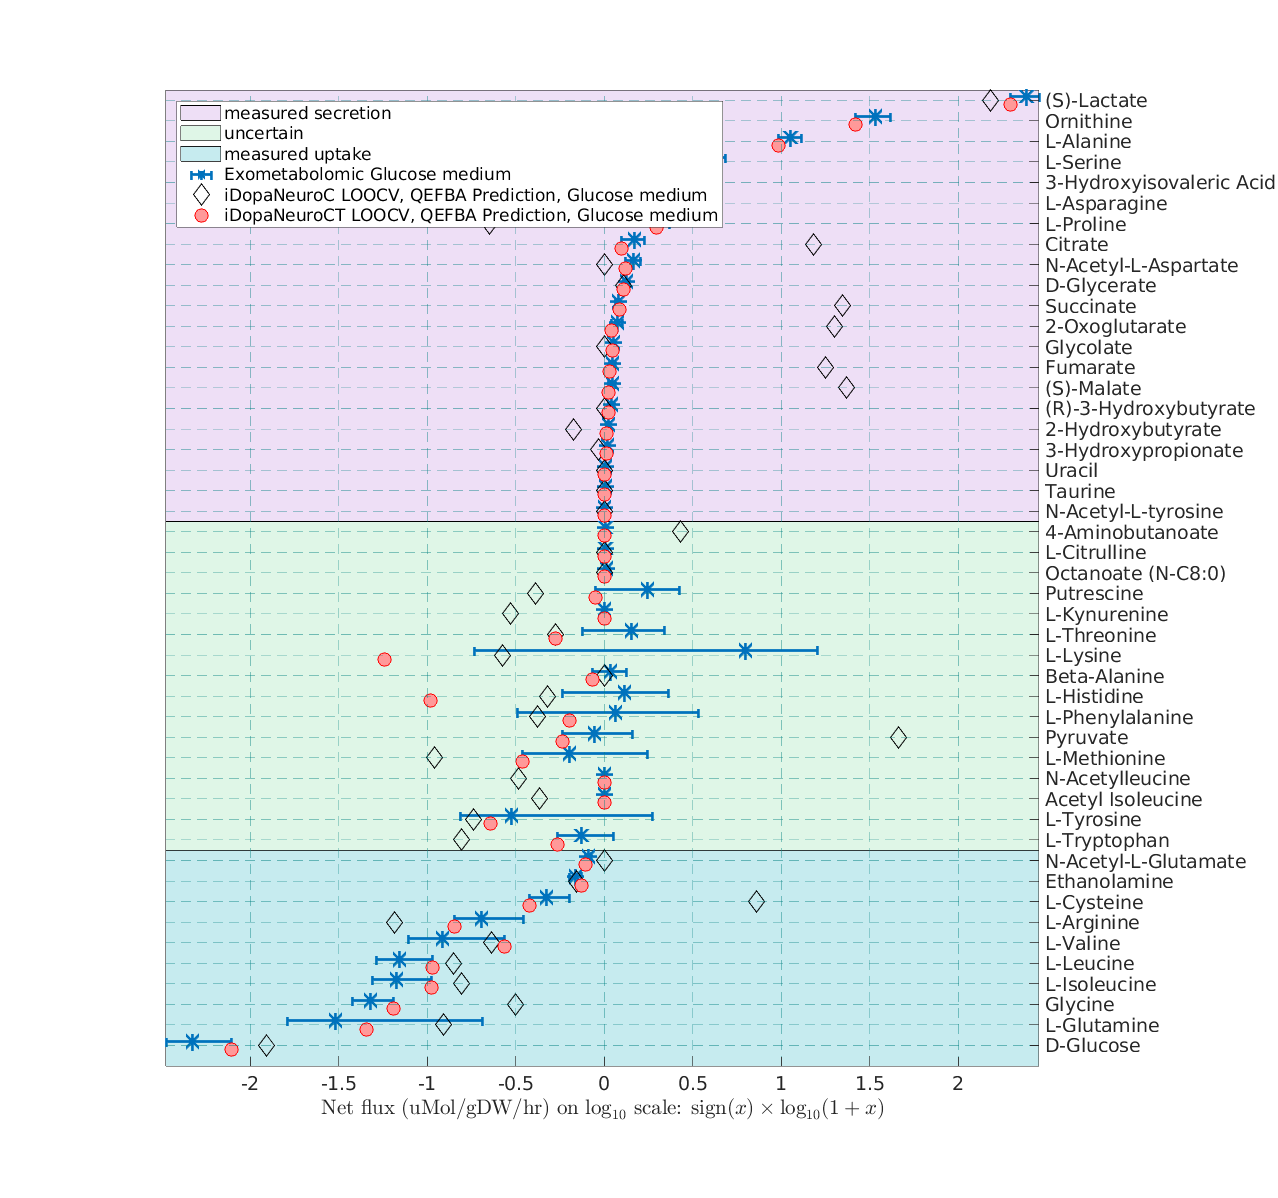

param.predictedBounds = 0;
param.otherBounds=0;
plotExperimentalvsPredictedExchange(glcValidationData, iDopaNeuroC_LOOCVPrediction, iDopaNeuroCT_LOOCVPrediction, [],param)

## Plot ATP and NADH balances in the control models

Uses the param.treshold_v to display only the reactions that carry significant flux

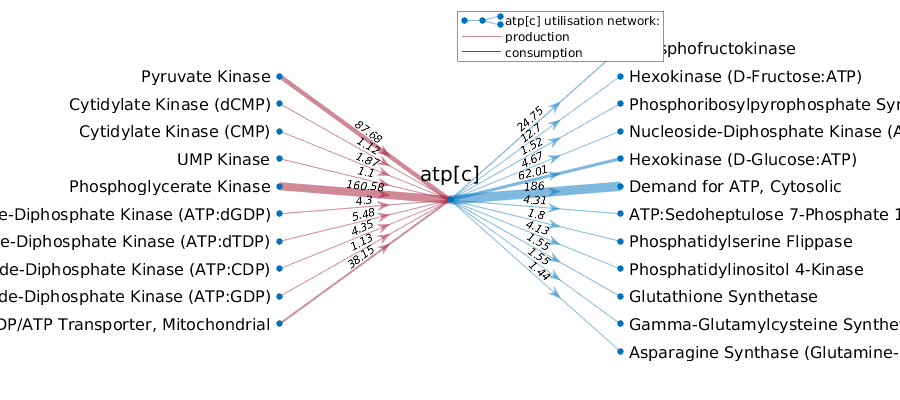

param.treshold_v = 1;
param.NodeLabels = 'rxnNames';
[atpGraphiDopaNeuroC,atpSummaryGraphiDopaNeuroC] = metUtilisation(iDopaNeuroCOrig, 'atp[c]', iDopaNeuroC_QEFBA.v, 1, param);
savefig([resultsDir filesep 'atpUtilisationiDopaNeuroC'])
saveas(gcf,[resultsDir filesep 'atpUtilisationiDopaNeuroC'],'png')

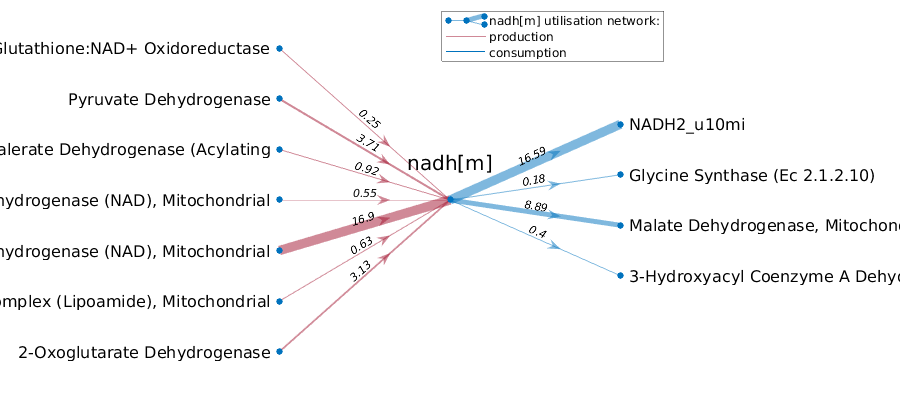

param.treshold_v = 0.1;
[nadhGraphiDopaNeuroC,nadhSummaryGraphiDopaNeuroC] = metUtilisation(iDopaNeuroCOrig, 'nadh[m]', iDopaNeuroC_QEFBA.v, 1, param);
savefig([resultsDir filesep 'nadhUtilisationiDopaNeuroC'])
saveas(gcf,[resultsDir filesep 'nadhUtilisationiDopaNeuroC'],'png')

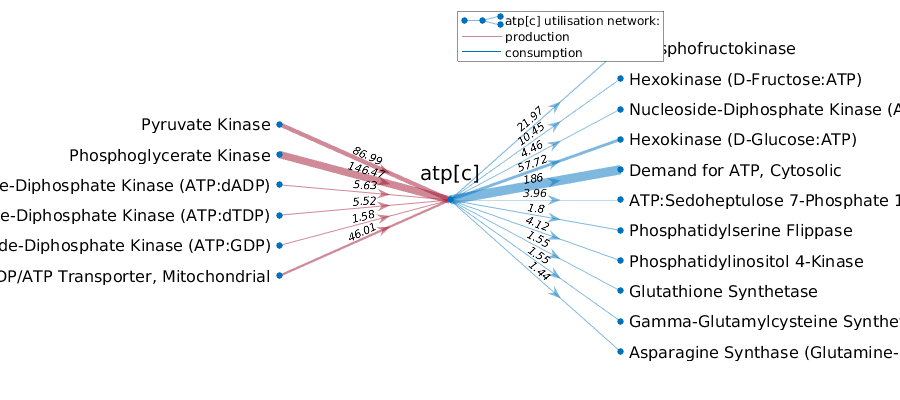

param.treshold_v = 1;
param.NodeLabels = 'rxnNames';
[atpGraphiDopaNeuroCT,atpSummaryGraphiDopaNeuroCT] = metUtilisation(iDopaNeuroCTOrig, 'atp[c]', iDopaNeuroCT_QEFBA.v, 1, param);
savefig([resultsDir filesep 'atpUtilisationiDopaNeuroCT'])
saveas(gcf,[resultsDir filesep 'atpUtilisationiDopaNeuroCT'],'png')

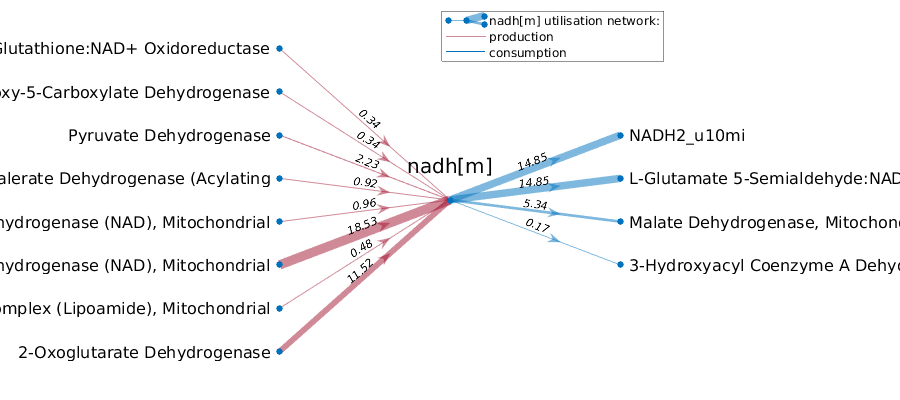

param.treshold_v = 0.1;
[nadhGraphiDopaNeuroCT,nadhSummaryGraphiDopaNeuroCT] = metUtilisation(iDopaNeuroCTOrig, 'nadh[m]', iDopaNeuroCT_QEFBA.v, 1, param);
savefig([resultsDir filesep 'nadhUtilisationiDopaNeuroCT'])
saveas(gcf,[resultsDir filesep 'nadhUtilisationiDopaNeuroCT'],'png')

## Summary table for ATP and NADH utilisation

summaryTableUtilisations = table({'Total ATP[c] reactions'}, length(atpSummaryGraphiDopaNeuroC.rxns),length(atpSummaryGraphiDopaNeuroC.rxns));
summaryTableUtilisations.Properties.VariableNames = {'Variable', 'iDopaNeuroC', 'iDopaNeuroCT'};
summaryTableUtilisations(end+1,:) = table({'Active ATP[c] producers'}, ...
    sum(atpSummaryGraphiDopaNeuroC.scoff.*round(atpSummaryGraphiDopaNeuroC.flux_v,6) > 0), ...
    sum(atpSummaryGraphiDopaNeuroCT.scoff.*round(atpSummaryGraphiDopaNeuroCT.flux_v,6) > 0));
summaryTableUtilisations(end+1,:) = table({'Active ATP[c] consumers'}, ...
    sum(atpSummaryGraphiDopaNeuroC.scoff.*round(atpSummaryGraphiDopaNeuroC.flux_v,6) < 0), ...
    sum(atpSummaryGraphiDopaNeuroCT.scoff.*round(atpSummaryGraphiDopaNeuroCT.flux_v,6) < 0));
summaryTableUtilisations(end+1,:) = table({'Total NADH[m] reactions'}, ...
    length(nadhSummaryGraphiDopaNeuroC.rxns), ...
    length(nadhSummaryGraphiDopaNeuroCT.rxns));
summaryTableUtilisations(end+1,:) = table({'Active NADH[m] producers'}, ...
    sum(nadhSummaryGraphiDopaNeuroC.scoff.*round(nadhSummaryGraphiDopaNeuroC.flux_v,6) > 0), ...
    sum(nadhSummaryGraphiDopaNeuroCT.scoff.*round(nadhSummaryGraphiDopaNeuroCT.flux_v,6) > 0));
summaryTableUtilisations(end+1,:) = table({'Active NADH[m] consumers'}, ...
    sum(nadhSummaryGraphiDopaNeuroC.scoff.*round(nadhSummaryGraphiDopaNeuroC.flux_v,6) < 0), ...
    sum(nadhSummaryGraphiDopaNeuroCT.scoff.*round(nadhSummaryGraphiDopaNeuroCT.flux_v,6) < 0));
display(summaryTableUtilisations)

summaryTableUtilisations = 6×3 table
              Variable              iDopaNeuroC    iDopaNeuroCT
    ____________________________    ___________    ____________

    {'Total ATP[c] reactions'  }        153            153     
    {'Active ATP[c] producers' }         16             17     
    {'Active ATP[c] consumers' }         21             22     
    {'Total NADH[m] reactions' }         51             62     
    {'Active NADH[m] producers'}          8             10     
    {'Active NADH[m] consumers'}          6              8     


Unrecognized function or variable 'summaryTableAll'.